# Formatos y transformaciones simples

Los formatos utilizados en Matlab son los siguientes:

imformats

 
EXT       ISA     INFO        READ      WRITE     ALPHA  DESCRIPTION                     
-----------------------------------------------------------------------------------------
bmp       isbmp   imbmpinfo   readbmp   writebmp  0      Windows Bitmap
cur       iscur   imcurinfo   readcur             1      Windows Cursor resources
fts fits  isfits  imfitsinfo  readfits            0      Flexible Image Transport System
gif       isgif   imgifinfo   readgif   writegif  0      Graphics Interchange Format
hdf       ishdf   imhdfinfo   readhdf   writehdf  0      Hierarchical Data Format
ico       isico   imicoinfo   readico             1      Windows Icon resources
j2c j2k   isjp2   imjp2info   readjp2   writej2c  0      JPEG 2000 (raw codestream)
jp2       isjp2   imjp2info   readjp2   writejp2  0      JPEG 2000 (Part 1)
jpf jpx   isjp2   imjp2info   readjp2             0      JPEG 2000 (Part 2)
jpg jpeg  isjpg   imjpginfo   readjpg   writejpg  0      Joint Photographic Experts Group
pb

Vizualizar los efectos de cambiar el formato de imágenes

load clown.mat;
    X, map

X =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
    61    69    69    69    69    69    69    69    69    69    69    69    69    69    61    69    61    69    69    69    61    61    61    69    61    69    61    69    61    69    61    61    61    69    61    61    61    69    61    69    61    69    61    69    61    61    61    61    55    61
    69    61    69    61    69    59    69    59    69    69    69    59    69    43    61    59    69    61    69    59    69    55    61    55    61    59    69    69    69    61    69    59    69    61    69    61    69    55    61    59    69    59    61    55    69    43    61    43    61    43
    61    69    61    61    56    61    61    61    61    69    61    69    61    61    61   

map =          0         0         0
    0.1250         0         0
    0.1250         0    0.1250
    0.2891         0         0
    0.2891         0    0.1250
    0.1250    0.1250         0
    0.4141         0         0
    0.1250    0.1250    0.1250
    0.2891    0.1250         0
    0.5781         0         0


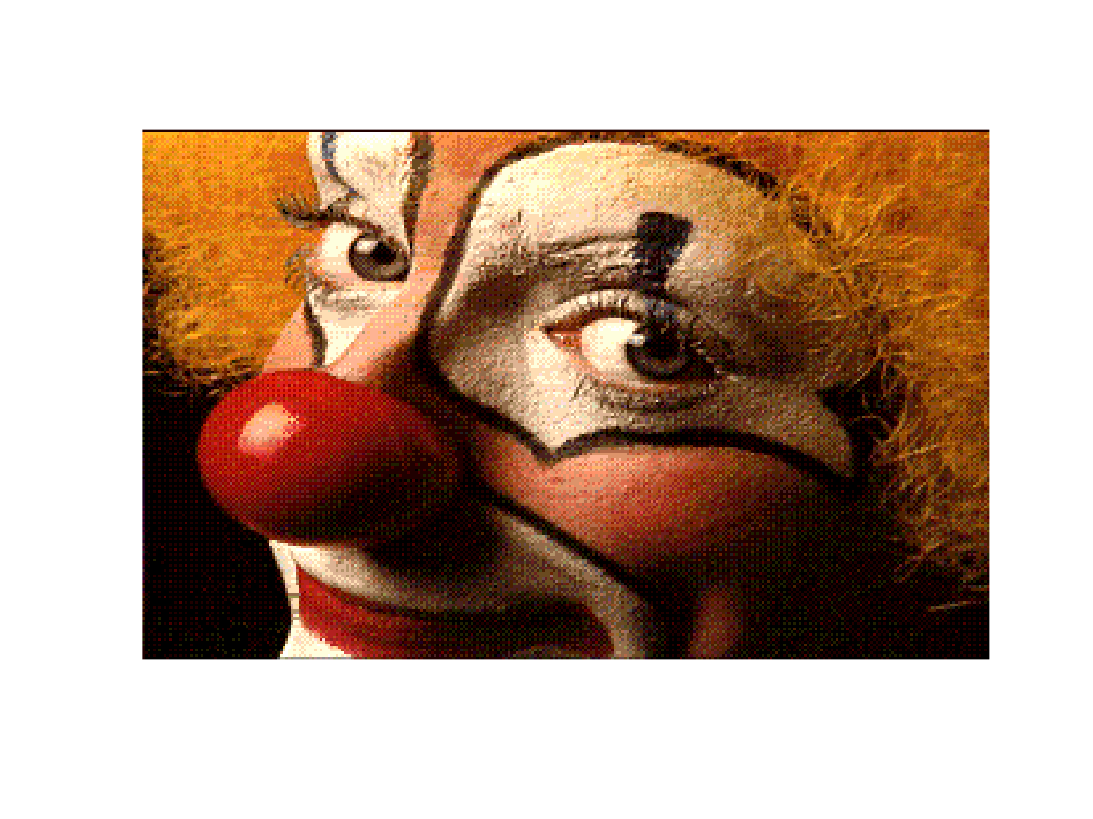

RGBclown = ind2rgb(X,map);
%     RGBclown = f(X,map);
% Otra froma de obtener imagenes en Matalab
% RGBclown = imread('comosellamamiimagen.extension');
imshow(RGBclown)

imwrite(RGBclown,'imagenes/myRGBclown.png');
imfinfo('imagenes/myRGBclown.png')

ans = struct with fields:
                  Filename: '/MATLAB Drive/CV/imagenes/myRGBclown.png'
               FileModDate: '11-Feb-2025 01:42:48'
                  FileSize: 52395
                    Format: 'png'
             FormatVersion: []
                     Width: 320
                    Height: 200
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '11 Feb 2025 01:42:48 +0000'
  

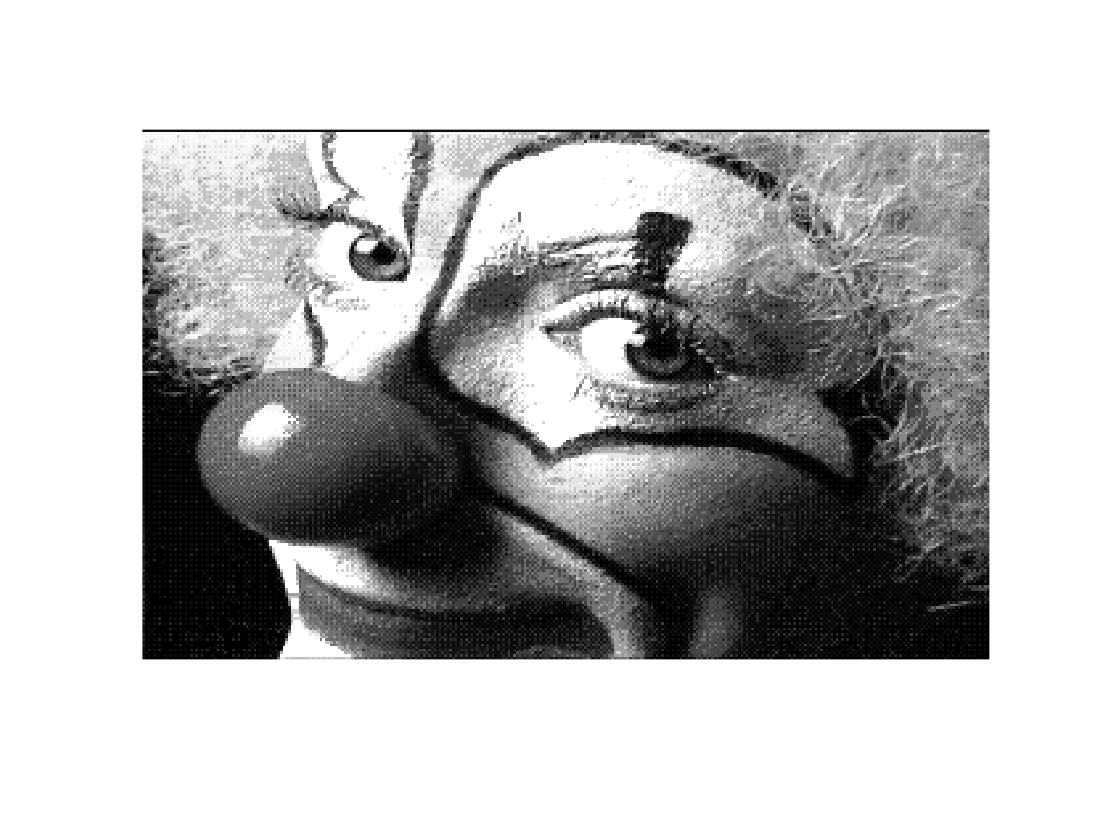

rgbClown(:,:,1) = 0.8*RGBclown(:,:,2) + 0.5*RGBclown(:,:,1);
imshow(rgbClown)

## Escala de grises

Convertir a una imagen en escala de grises

MatrizGris = coeficienteRojo*MatrizRojo + coeficienteVerde*MatrizVerde + coeficienteAzul*MatrizAzul

Para imagenes indizadas la conversion es la siguiente

MatrizOriginal(i,j) = k %  color RGB

MatrizGris(i,j) = coeficienteRojo*mapRojo(k) + coeficienteVerde*mapVerde(k) + coeficienteAzul*mapAzul(k)

Para evitar la suma de MatrizGris(i,j) de mayor a 1

coeficienteRojo + coeficienteVerde + coeficienteAzul = 1

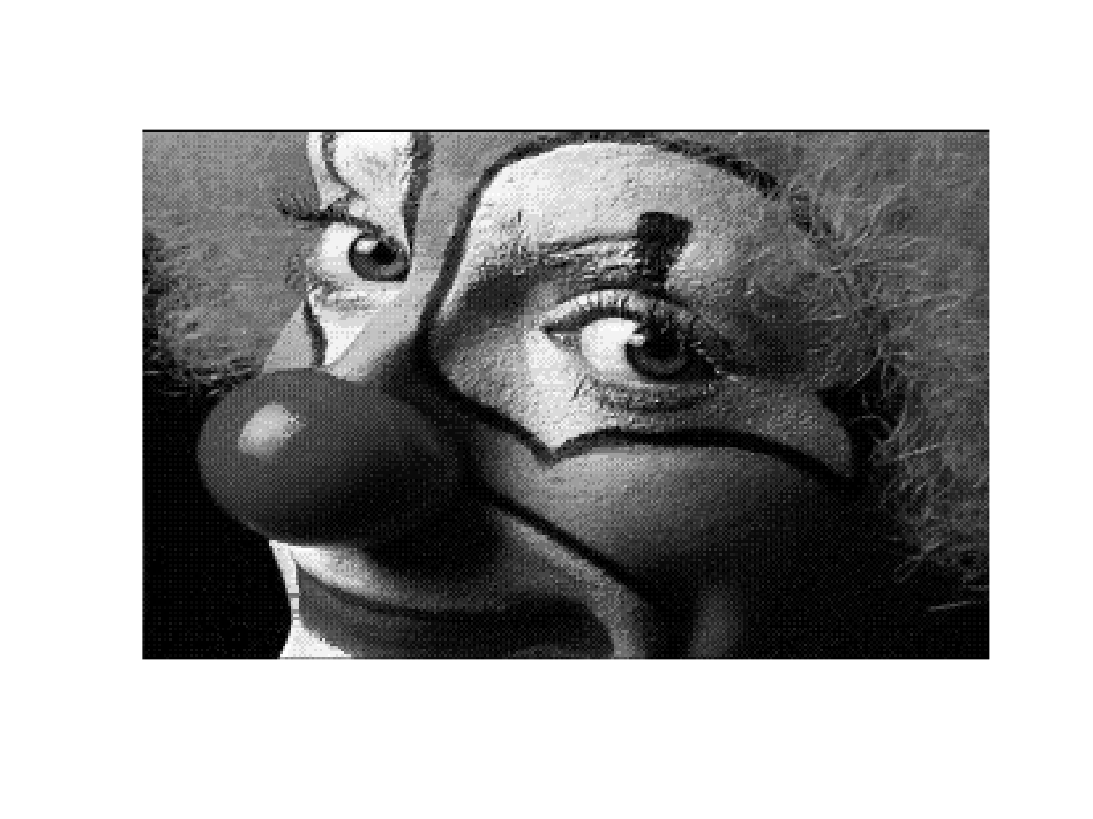

grayClown = (0.333)*RGBclown(:,:,1) + (0.333)*RGBclown(:,:,2) + (0.3333)*RGBclown(:,:,3);
imshow(grayClown);

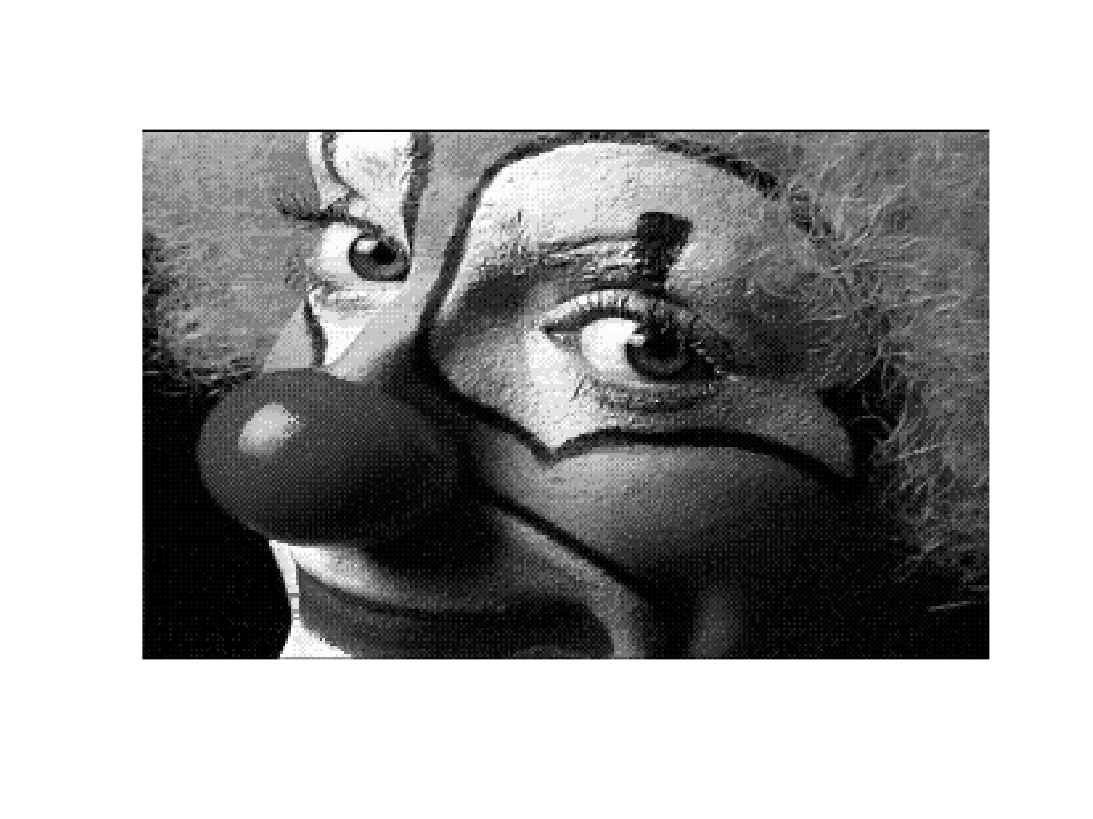

GrayClown = ind2gray(X,map);
imshow(GrayClown)

imwrite(GrayClown,'imagenes/myGrayClown.jpg');
imfinfo('imagenes/myGrayClown.jpg')

ans = struct with fields:
              Filename: '/MATLAB Drive/CV/imagenes/myGrayClown.jpg'
           FileModDate: '11-Feb-2025 01:42:49'
              FileSize: 18805
                Format: 'jpg'
         FormatVersion: ''
                 Width: 320
                Height: 200
              BitDepth: 8
             ColorType: 'grayscale'
       FormatSignature: ''
       NumberOfSamples: 1
          CodingMethod: 'Huffman'
         CodingProcess: 'Sequential'
               Comment: {}
     AutoOrientedWidth: 320
    AutoOrientedHeight: 200


Matlab convierte los valores RGB en valores de escala de grises formando una suma ponderada de los componentes R, G y B:

0.2989 * R + 0,5870 * G + 0,1140 * B

La Recomendación **UIT-R BT.601-7**, Unión internacional de Comunicaciónes, del sector de Radiocomunicaciones. Esta recomendación ayuda a la conversión para la codificación digital para la televisión digital. Determinando las frecuencias de muestro, cuantificación, relación de aspecto, luminancia, cromancias, diferencias de color, etc.

## Histograma de una imágen

grayClown = (0.1)*RGBclown(:,:,1) + (0.1)*RGBclown(:,:,2) + (0.1)*RGBclown(:,:,3)

grayClown =     0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125
    0.1699    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1824    0.1699    0.1824    0.1699    0.1824    0.1824    0.1824    0.1699    0.1699    0.1699    0.1824    0.1699    0.1824    0.1699    0.1824    0.1699    0.1824    0.1699    0.1699    0.1699    0.1824    0.1699    0.1699    0.1699    0.1824    0.1699    0.1824    0.1699    0.1824    0.1699    0.1824    0.1699    0.1699    0.1699    0.1699    0.1

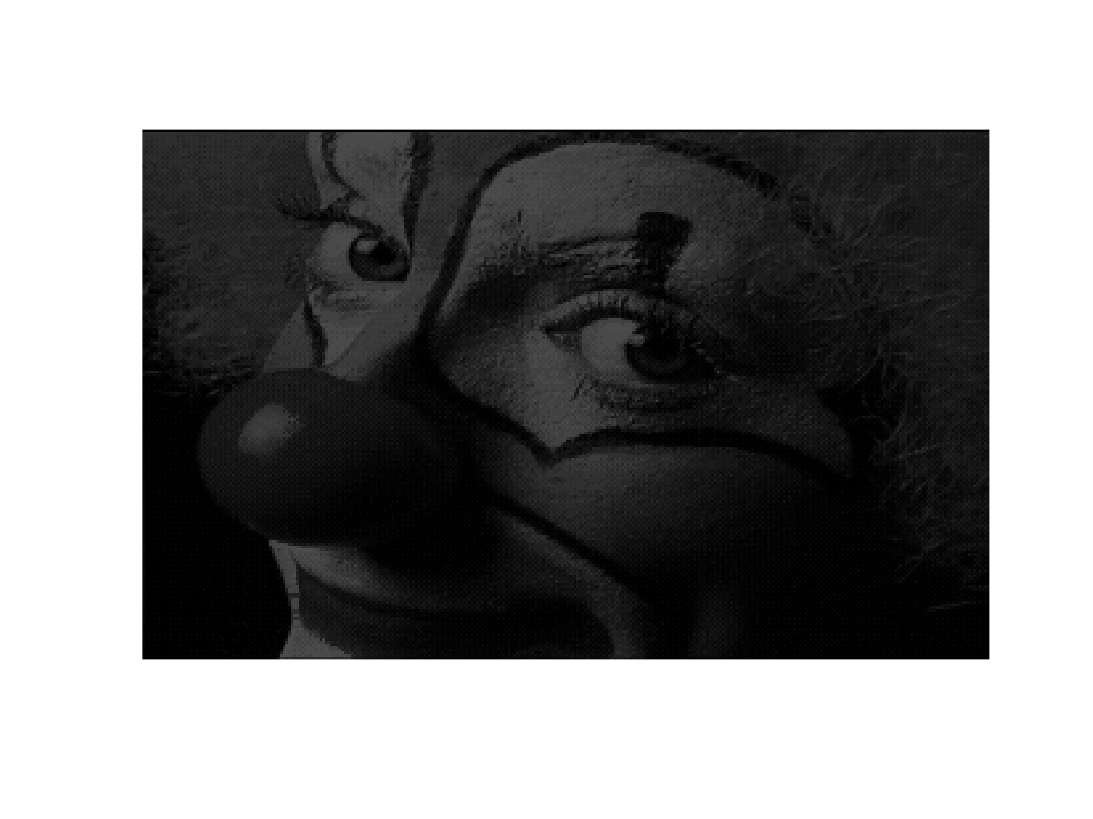


imshow(grayClown);

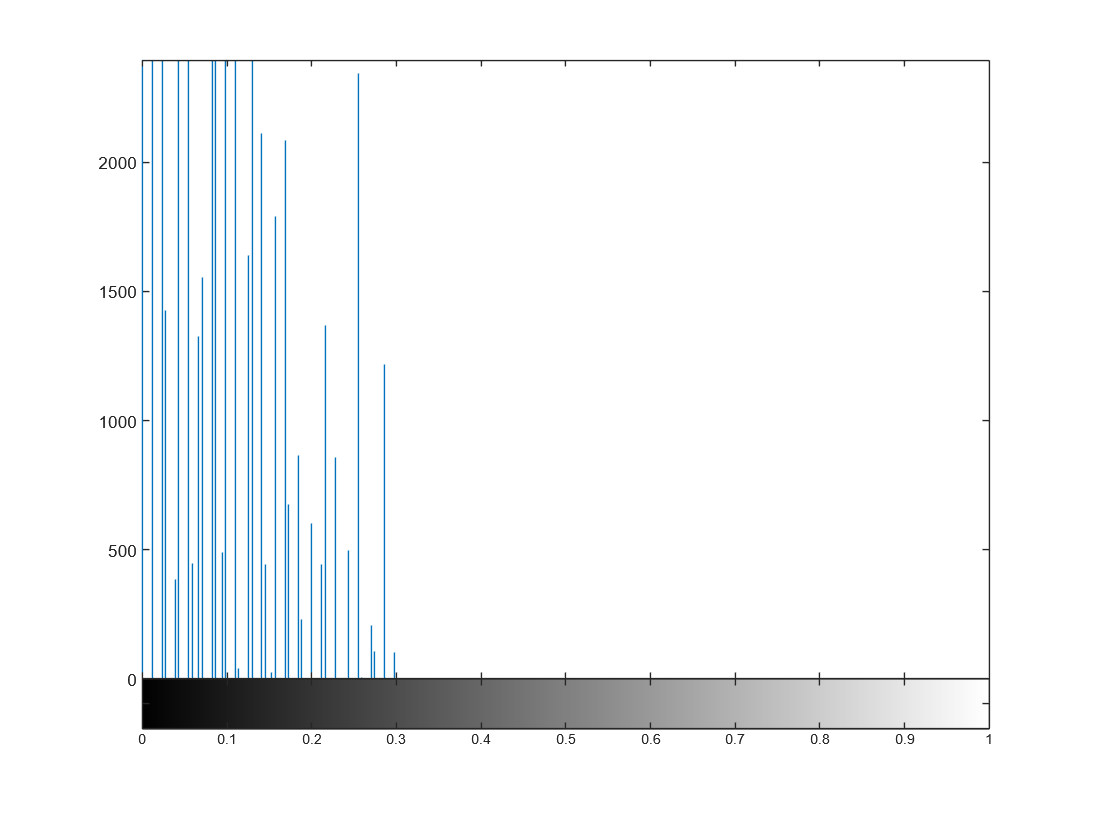

% imshow(0.25 < grayClown & grayClown < 1)
imhist(grayClown);

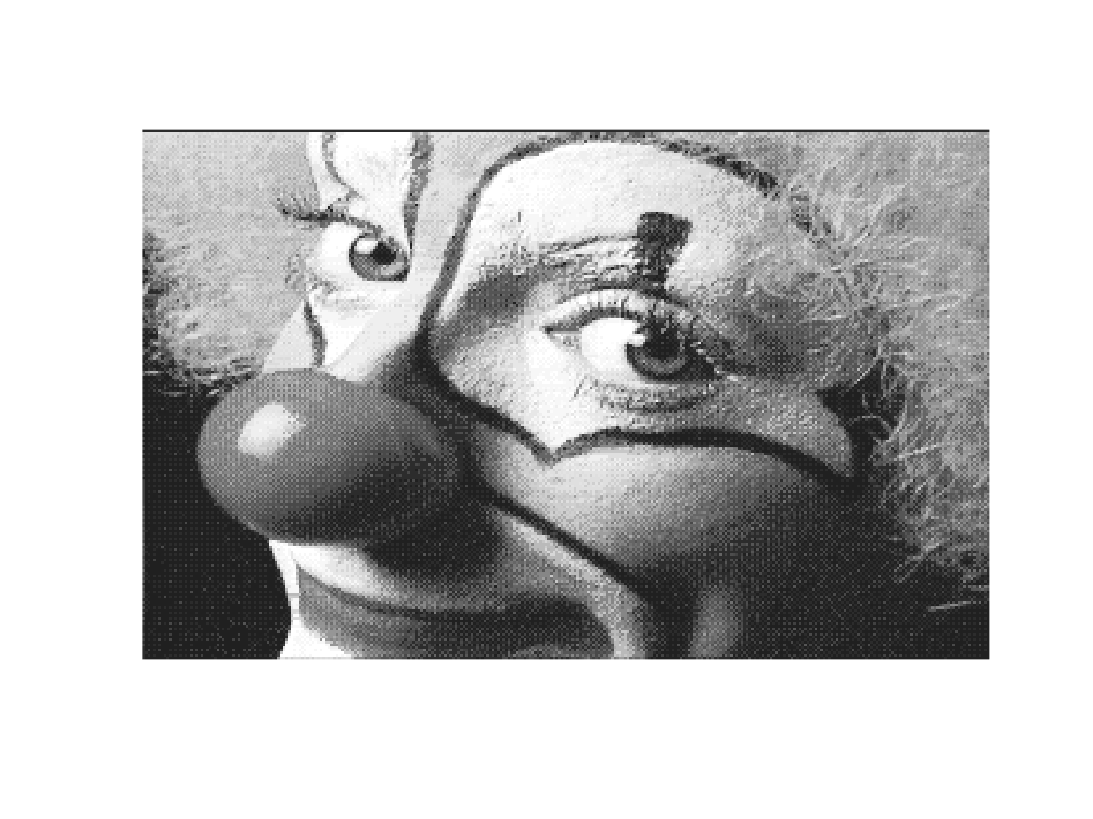

[grayClownBis, scale] = histeq(grayClown);
imshow(grayClownBis);

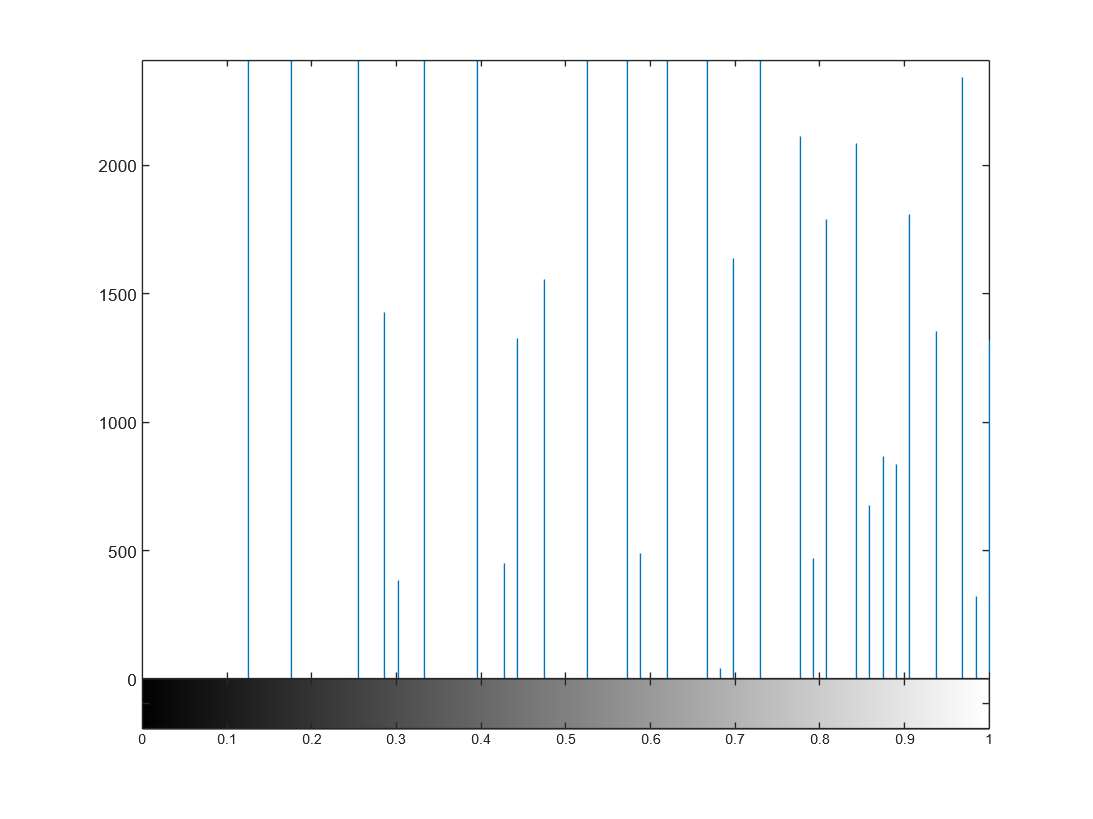

imhist(grayClownBis);

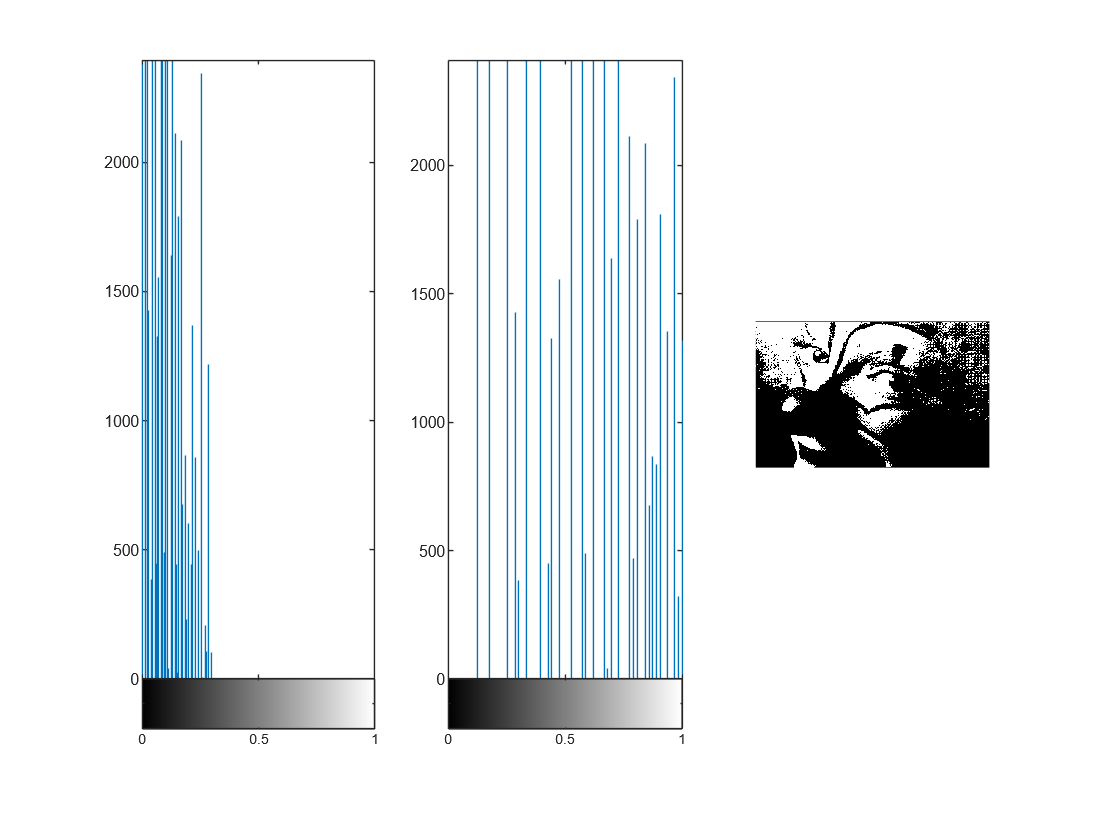

subplot(1,3,1);       imhist(grayClown);
subplot(1,3,2);       imhist(grayClownBis);
subplot(1,3,3);        plot((0:255)/255,scale);


% xlim([0.093 0.920])
% ylim([0.12 0.95])

BW = imbinarize(grayClown);
imshow(BW);